# COTS Ensemble Live Script 21

## Set Interpreter

setInterpLatex()

## Contents

COTS Density Imputation

Larval Supply Figures

## Assumptions

## COTS Density Imputation

% load in the density data
cotsDensData = readtable("../Data/Matlab Transfer/cotsDensData.csv");

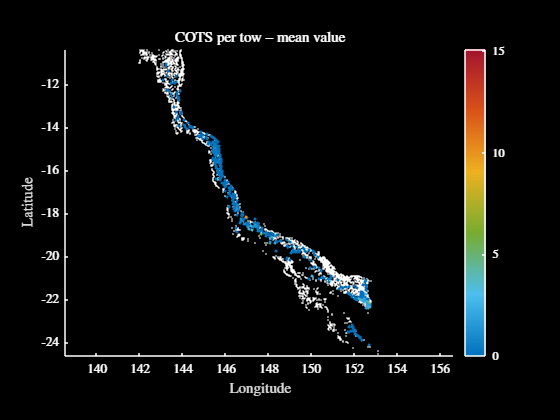

% let's just visualise it real quick
figure
hold on
plotPoints(centroidsLL, 'markerSize', 0.1)
scatter(cotsDensData.x, cotsDensData.y, 6, ...
    cotsDensData.cotsPerTowMean, 'filled')
colormap(myColourMap("dmTurbo"))
axis equal
colorbar()
title("COTS per tow -- mean value")
xlabel("Longitude")
ylabel("Latitude")
darkFig()

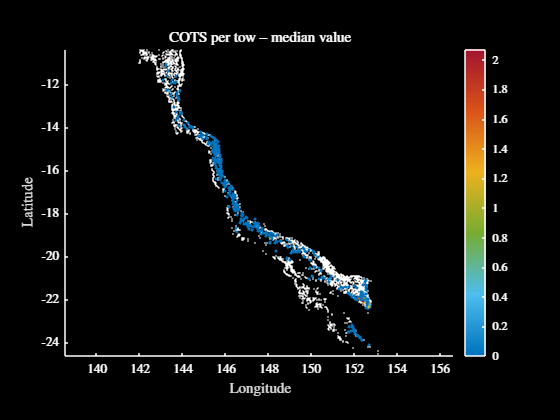

% let's just visualise it real quick
figure
hold on
plotPoints(centroidsLL, 'markerSize', 0.1)
scatter(cotsDensData.x, cotsDensData.y, 6, ...
    cotsDensData.cotsPerTowMedian, 'filled')
colormap(myColourMap("dmTurbo"))
axis equal
colorbar()
title("COTS per tow -- median value")
xlabel("Longitude")
ylabel("Latitude")
darkFig()

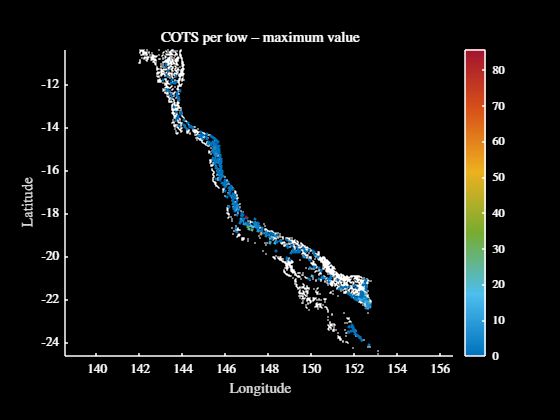

figure
hold on
plotPoints(centroidsLL, 'markerSize', 0.1)
scatter(cotsDensData.x, cotsDensData.y, 6, ...
    cotsDensData.cotsPerTowMax, 'filled')
colormap(myColourMap("dmTurbo"))
axis equal
colorbar()
title("COTS per tow -- maximum value")
xlabel("Longitude")
ylabel("Latitude")
darkFig()

## Larval Supply Figures

% alright, now need to load in the outbreaking data
outbreakDataMatlab = readtable("../Data/Matlab Transfer/" + ...
    "outbreakDataMatlab");
outbreakData = readtable("../Data/Matlab Transfer/outbreakData");

% let's make some masks so that my life is easier
outbrReefs = outbreakDataMatlab.outbreak == 1;
nonOutbrReefs = outbreakDataMatlab.outbreak == 0;
obsReefs = (outbreakDataMatlab.outbreak == 0) ...
    + (outbreakDataMatlab.outbreak == 1) > 0;

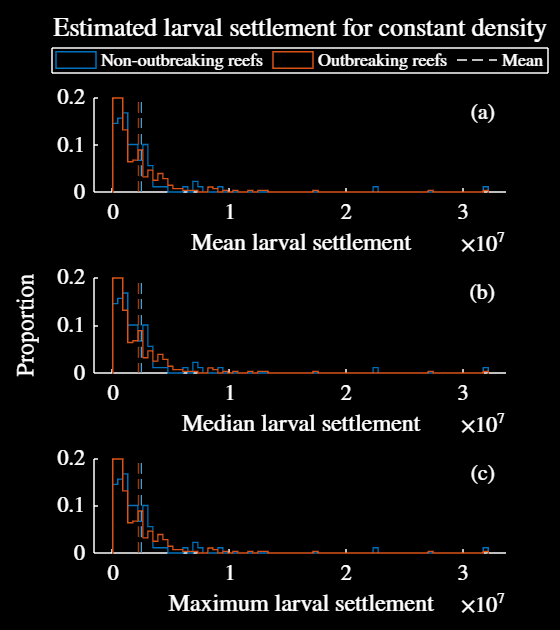

% alright let's do one where I assume everywhere has a constant cots
% density of 1 cots per tow, basically then just summing the incoming
% connections multiplied by the area
cotsDensBrt = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");
cotsDensBrt.cotsPerTowMeanImput = ones(size( ...
    cotsDensBrt.cotsPerTowMeanImput));
cotsDensBrt.cotsPerTowMedianImput = ones(size( ...
    cotsDensBrt.cotsPerTowMeanImput));
cotsDensBrt.cotsPerTowMaxImput = ones(size( ...
    cotsDensBrt.cotsPerTowMeanImput));

% first do the histograms
figure
figResize(1.5, 1)
var1 = ["", "DM"];
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement for constant " + ...
        "density", i == 2, true)
    saveFig("estimatedLarvSuppConstDensHist" + var1(i))
end

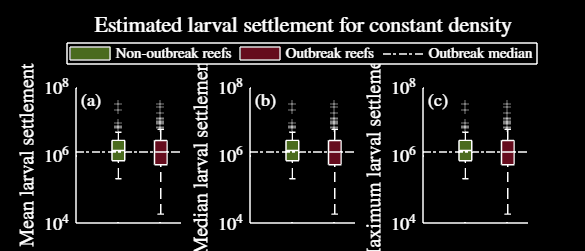


% then do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement for constant " + ...
        "density", i == 2, false)
    saveFig("estimatedLarvSuppConstDens" + var1(i))
end

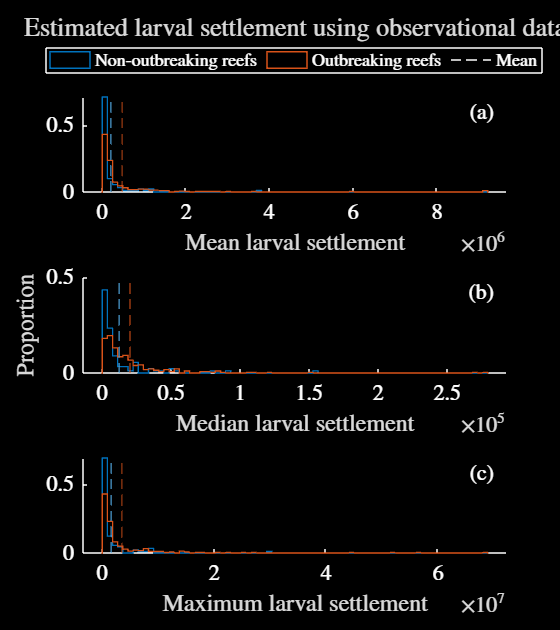

% let's plot the results when we do no imputation, and just use the
% observational data directly
cotsDensNoImput = readtable("../Data/Matlab Transfer/cotsDensNoImput.csv");
var1 = ["", "DM"];
figure
figResize(1.5, 1)

% loop over the light and dark mode figures
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensNoImput, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using observational " + ...
        "data", i == 2)
    saveFig("estimatedLarvSuppNoInterpHist" + var1(i))
end

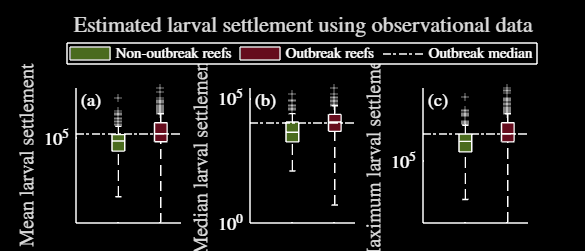


% now do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensNoImput, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using observational " + ...
        "data", i == 2, false)
    saveFig("estimatedLarvSuppNoInterp" + var1(i))
end

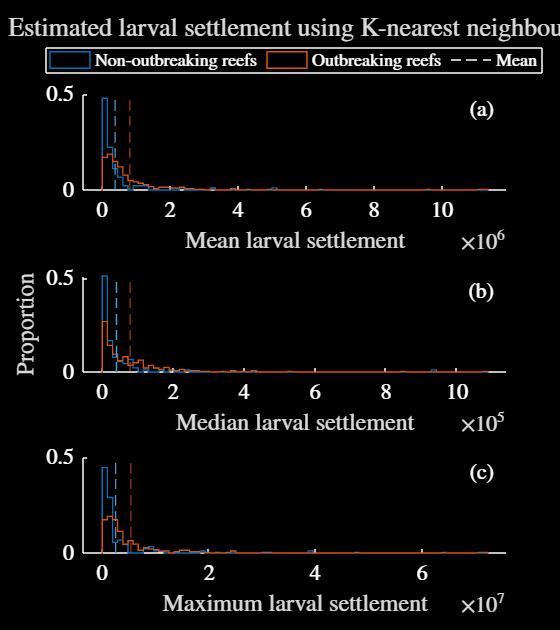

% let's plot the results when use a knn for the imputation
cotsDensKnn = readtable("../Data/Matlab Transfer/cotsDensKnn.csv");
figure
figResize(1.5, 1)

% loop over the light and dark mode figures
var1 = ["", "DM"];
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensKnn, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using " + ...
        "K-nearest neighbours", ...
        i == 2)
    saveFig("estimatedLarvSuppKnnHist" + var1(i))
end

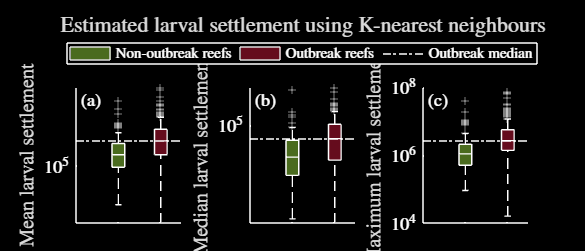


% how do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensKnn, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using " + ...
        "K-nearest neighbours", ...
        i == 2, false)
    saveFig("estimatedLarvSuppKnn" + var1(i))
end

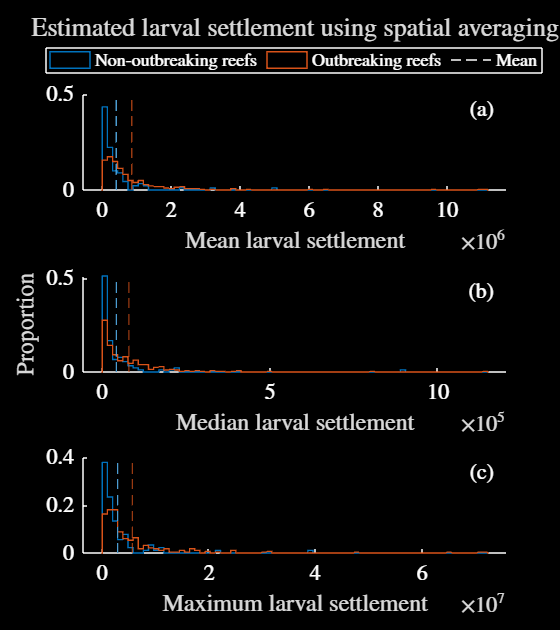

% now let's do the spatial averaging approach
cotsDensSpatAve = readtable("../Data/Matlab Transfer/cotsDensSpatAve.csv");
figure
figResize(1.5, 1)
var1 = ["", "DM"];
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensSpatAve, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using " + ...
        "spatial averaging", ...
        i == 2)
    saveFig("estimatedLarvSuppSpatAveHist" + var1(i))
end

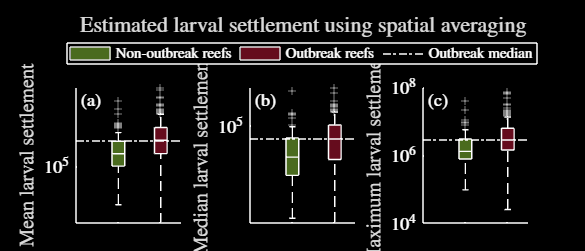


% then do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensSpatAve, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using " + ...
        "spatial averaging", ...
        i == 2, false)
    saveFig("estimatedLarvSuppSpatAve" + var1(i))
end

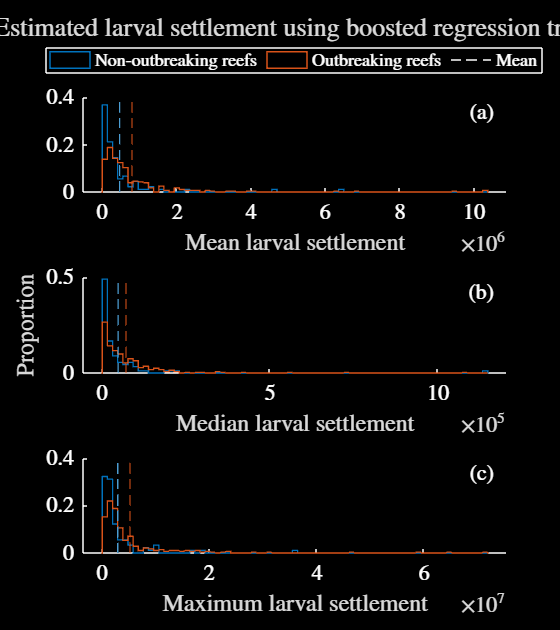

% now let's do the brt approach V2
cotsDensBrt = readtable("../Data/Matlab Transfer/" + ...
    "cotsDensBrtV2.csv");

% first do the histograms
figure
figResize(1.5, 1)
var1 = ["", "DM"];
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using boosted " + ...
        "regression trees", i == 2, true)
    saveFig("estimatedLarvSuppBrtHistV2" + var1(i))
end

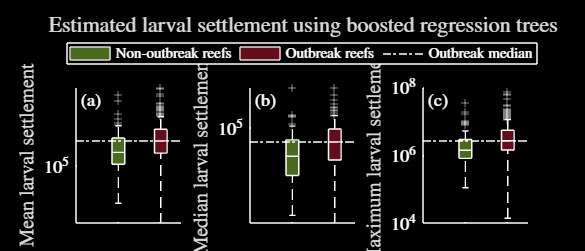


% then do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using boosted " + ...
        "regression trees", i == 2, false)
    saveFig("estimatedLarvSuppBrtV2" + var1(i))
end

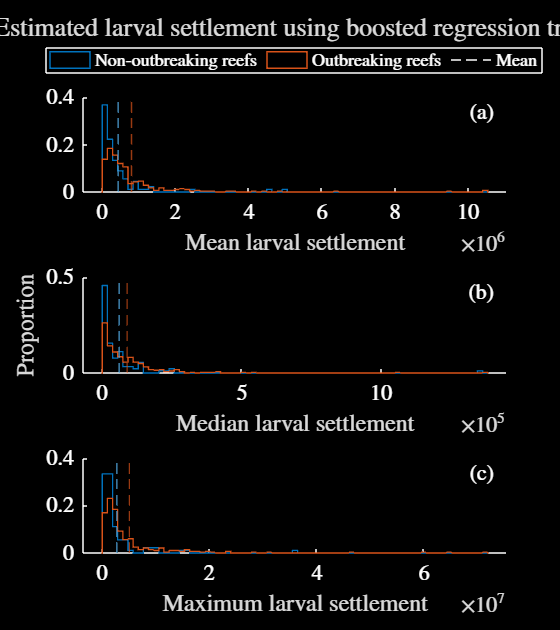

% now let's do the brt approach V3
cotsDensBrt = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");

% first do the histograms
figure
figResize(1.5, 1)
var1 = ["", "DM"];
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using boosted " + ...
        "regression trees", i == 2, true)
    saveFig("estimatedLarvSuppBrtHistV3" + var1(i))
end

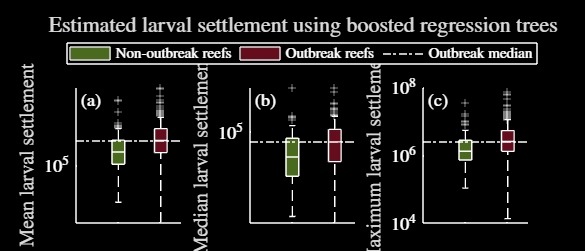


% then do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using boosted " + ...
        "regression trees", i == 2, false)
    saveFig("estimatedLarvSuppBrtV3" + var1(i))
end

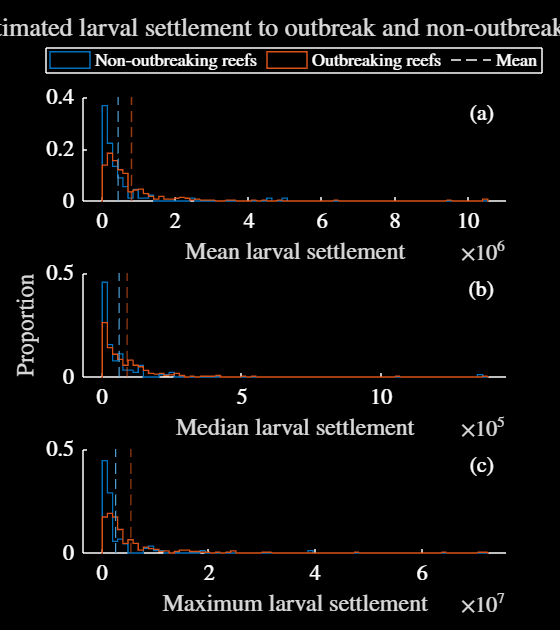

% alright let's do the final one, where I'm using the brt for both mean and
% median, and then the knn for the maximum
cotsDensBrt = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");
var1 = readtable("../Data/Matlab Transfer/cotsDensKnn.csv");
cotsDensBrt.cotsPerTowMaxImput = var1.cotsPerTowMaxImput;

% first do the histograms
figure
figResize(1.5, 1)
var1 = ["", "DM"];
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement to outbreak and " + ...
        "non-outbreak reefs", i == 2, true)
    saveFig("estimatedLarvSuppHist" + var1(i))
end

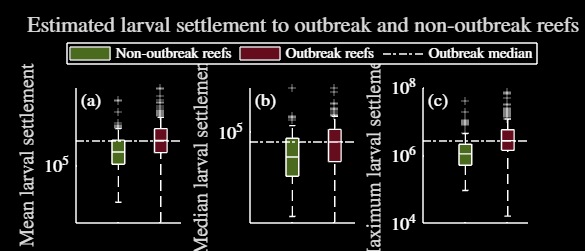


% then do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement to outbreak and " + ...
        "non-outbreak reefs", i == 2, false)
    saveFig("estimatedLarvSupp" + var1(i))
end

## Spatial Averages Visualisation

% I wanna actually have a look at the observations we have, and eyeball
% whether or not there is much spatial autocorrelation
cotsDensData = readtable("../Data/Matlab Transfer/cotsDensData.csv");

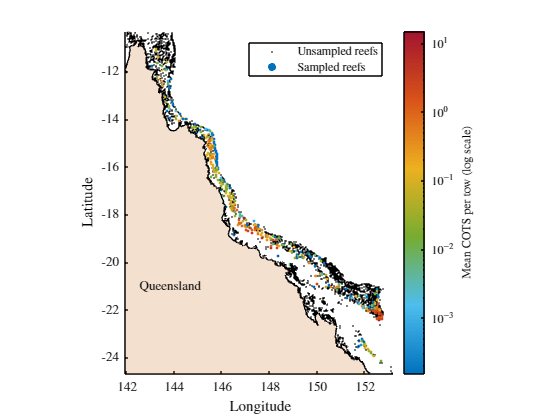

% plot stufv :3
figure
hold on
plotPoints(centroidsLL)
scatter(cotsDensData.x, cotsDensData.y, 4, ...
    cotsDensData.cotsPerTowMean, 'filled')
colormap(myColourMap("dmTurbo"))
set(gca, 'colorscale', 'log')
cBar = colorbar();
ylabel(cBar, "Mean COTS per tow (log scale)", "Interpreter", "latex")
latLonLabs
plotQldOutline(qldOutline)
legend("Unsampled reefs", "Sampled reefs", 'location', 'northeast')
axis equal
axis(gbrBoundaryLL)
darkFig()
saveFig("cotsPerTowObsMeanDM")
lightFig()
saveFig("cotsPerTowObsMean")

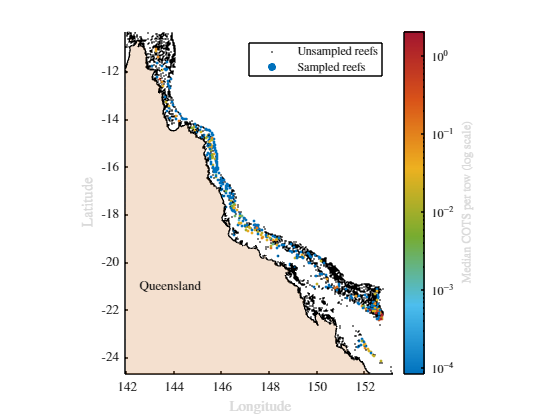

figure
hold on
plotPoints(centroidsLL)
scatter(cotsDensData.x, cotsDensData.y, 4, ...
    cotsDensData.cotsPerTowMedian, 'filled')
colormap(myColourMap("dmTurbo"))
set(gca, 'colorscale', 'log')
cBar = colorbar();
ylabel(cBar, "Median COTS per tow (log scale)", "Interpreter", "latex")
latLonLabs
plotQldOutline(qldOutline)
legend("Unsampled reefs", "Sampled reefs", 'location', 'northeast')
axis equal
axis(gbrBoundaryLL)
darkFig()
saveFig("cotsPerTowObsMedianDM")
lightFig()
saveFig("cotsPerTowObsMedian")

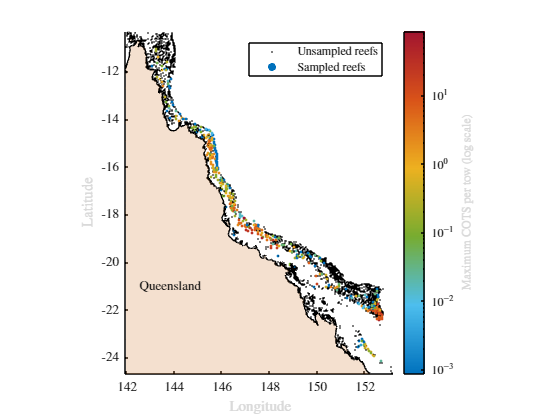

figure
hold on
plotPoints(centroidsLL)
scatter(cotsDensData.x, cotsDensData.y, 4, ...
    cotsDensData.cotsPerTowMax, 'filled')
colormap(myColourMap("dmTurbo"))
set(gca, 'colorscale', 'log')
cBar = colorbar();
ylabel(cBar, "Maximum COTS per tow (log scale)", "Interpreter", "latex")
latLonLabs
plotQldOutline(qldOutline)
legend("Unsampled reefs", "Sampled reefs", 'location', 'northeast')
axis equal
axis(gbrBoundaryLL)
darkFig()
saveFig("cotsPerTowObsMaxDM")
lightFig()
saveFig("cotsPerTowObsMax")

% let's look at our predictions of the mean, median, and maximum cots
% densities next to their true values so that I can try get a vague idea of
% whether the predictions look reasonable